# **Concept demonstrator: **  Color-Based Segmentation Using the L*a*b* Color Space

## **ATTENTION:**

- `this is a Bradified version of a shipping demo `

- `web(fullfile(docroot, 'images/examples/color-based-segmentation-using-the-l-a-b-color-space.html'))`

- ` - thanks Daryl for the heads up !`

This example shows how to identify different colors in a sample image taken from the Droid Racing Competition(DRC). 

The algorthm involves the development of a "nearest neighbour" classifier that processes color expressed in the L*a*b* colorspace. 

`Bradley Horton : 07-Jul-2017, bradley.horton@mathworks.com.au`

## Step 1:    Read Image

Read in the sample image 

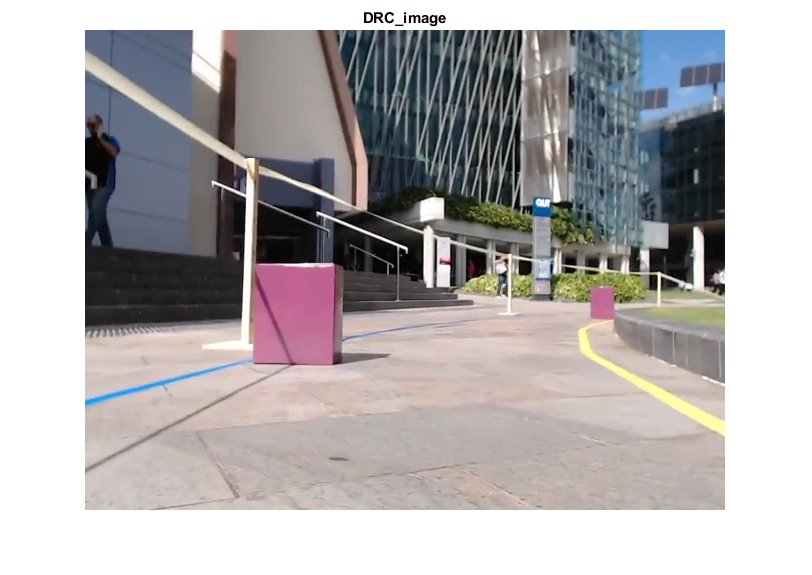

DRC_image = imread('bh_ref_11am_reverse.bmp');
figure;
imshow(DRC_image); title('DRC_image', 'Interpreter', 'none');

## Step 2: Calculate Sample Colors in L*a*b* Color Space for Each Region

We've decided that their are 6 colors (let's call them regions) that we want to categorise a pixel to.  These regions are:

- blue track tape

- yellow track tape

- purple obstacle box

- green grass/plants

- grey step from pavers to grass

- pavers

As a manual step, I've used the interactive version of the `roipoly()` function and manually selected an example of each color region.  The x,y co-ordinates of each polygon are stored in an Excel file.  Read XLS file containing color regions

A_tab = readtable('bh_color_lookup_bh_ref_11am_reverse.xlsx', 'Sheet', 'ALL');

region_coordinates        = [];
region_coordinates(:,:,1) = [A_tab.blue_x,     A_tab.blue_y];
region_coordinates(:,:,2) = [A_tab.yellow_x,   A_tab.yellow_y];
region_coordinates(:,:,3) = [A_tab.purple_x,   A_tab.purple_y];
region_coordinates(:,:,4) = [A_tab.green_x,    A_tab.green_y];
region_coordinates(:,:,5) = [A_tab.grey_rim_x, A_tab.grey_rim_y];
region_coordinates(:,:,6) = [A_tab.pavers_x,   A_tab.pavers_y];

color_labels_list         = {'blue', 'yellow','purple','green','grey_rim', 'pavers'};
nColors                   = 6;

Have a look at what we selected:

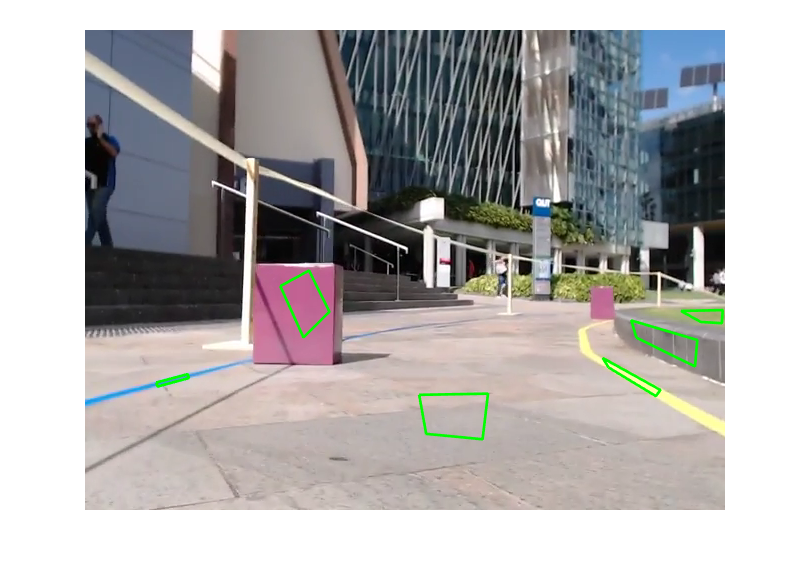

figure;
imshow(DRC_image);  hold on;

for kk=1:nColors
    A_mat = region_coordinates(:,:,kk);
    x     = A_mat(:,1);
    y     = A_mat(:,2);
    
    plot(x,y,'-g', 'LineWidth',2)
end

Next, we'll use another usage mode of `roipoly()` and get a binary mask matrix for each of our regions.  The binary mask matrix will be the same size as the `DRC_image`. Recall the usage of `roiploy()`

- `BW =` `roipoly``(I, c, r)`

BW_sample_regions    = false([size(DRC_image,1) size(DRC_image,2) nColors]);

for count = 1:nColors
  BW_sample_regions(:,:,count) = roipoly(DRC_image,region_coordinates(:,1,count),...
                                                   region_coordinates(:,2,count));
end

Let's visualize this:

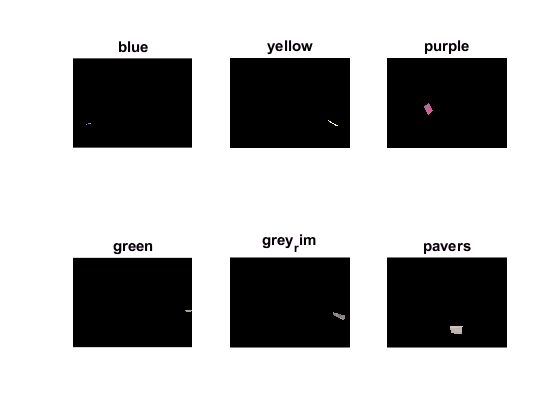

figure;

for kk=1:nColors    
    I     = zeros(size(DRC_image,1), size(DRC_image,2), 3, 'uint8');
    
    BW    = BW_sample_regions(:,:,kk);  % a    2D    matrix
    BW    = repmat(BW,1,1,3);           % a ***3D*** matrix
    I(BW) = DRC_image(BW);

    subplot(2,3,kk);  imshow(I),title(color_labels_list{kk});        
end

Convert your DRC_image RGB image into an L*a*b* image using `rgb2lab` .

lab_DRC_image = rgb2lab(DRC_image);

## Step 2:    Calculate the mean colors of each region

Calculate the mean 'a*' and 'b*' value for each area that we extracted with `roipoly`. These values serve as your color markers in 'a*b*' space.

a             = lab_DRC_image(:,:,2);
b             = lab_DRC_image(:,:,3);
color_markers = zeros([nColors, 2]);

for count = 1:nColors
                BW_mask  = BW_sample_regions(:,:,count);
                
  color_markers(count,1) = mean2( a(BW_mask) );
  color_markers(count,2) = mean2( b(BW_mask) );
end

## Step 3: Classify Each Pixel Using the Nearest Neighbor Rule

Each color marker now has an 'a*' and a 'b*' value. You can classify each pixel in the `lab_DRC_image` image by calculating the Euclidean distance between that pixel and each color marker. The smallest distance will tell you that the pixel most closely matches that color marker. For example, if the distance between a pixel and the yellow color marker is the smallest, then the pixel would be labeled as a yellow pixel.

Create an array that contains your color labels, i.e., 

- blue $\longrightarrow$ 0

- yellow $\longrightarrow$ 1

- purple $\longrightarrow$ 2

- green$\longrightarrow$ 3

- grey_rim $\longrightarrow$ 4

- pavers$\longrightarrow$ 5

color_labels = 0:nColors-1;

Initialize matrices to be used in the nearest neighbor classification.

a        = double(a);
b        = double(b);
distance = zeros([size(a,1), size(a,2), nColors]);

Perform classification

for count = 1:nColors
  distance(:,:,count) = ( (a - color_markers(count,1)).^2 + ...
                          (b - color_markers(count,2)).^2 ).^0.5;
end

Now find which 3rd dimensional "page" had the smallest distance for each pixel.

- REMEBER that the `ind` variable will be an MxN matrix

[~, ind] = min(distance,[],3);

Now create a label matrix, which is the same size as the DRC_image matrix ... but it contains label IDs for each pixel

label      = color_labels(ind);
%clear distance;

## Step 4: Display Results of Nearest Neighbor Classification

The label matrix contains a color label for each pixel in the `DRC_image` image. Use the label matrix to separate objects in the original `DRC_image` image by color.

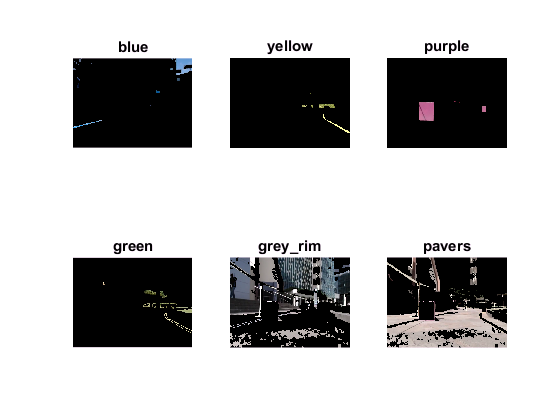

rgb_label = repmat(label,[1 1 3]);
segmented_images = zeros([size(DRC_image), nColors],'uint8');  % a 4D matrix

for count = 1:nColors
  color = DRC_image;
  color(rgb_label ~= color_labels(count)) = 0;
  segmented_images(:,:,:,count) = color;
end 

figure
for kk=1:nColors   
    I     = segmented_images(:,:,:,kk);
    subplot(2,3,kk);  imshow(I),title(color_labels_list{kk}, 'Interpreter', 'none');
        
end

## Step 5:  find the thin lane markings

Let's look for the BLUE and YELLOW lane markings:

BW_blue   = label == 0;
BW_yellow = label == 1;

Ignore the top half of the image:

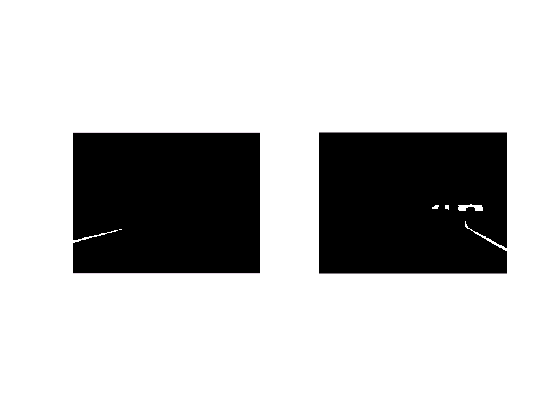

R_half = round(   size(DRC_image,1)/2   );

BW_blue(1:R_half, :) = 0;
BW_yellow(1:R_half, :) = 0;
%BW_blue = imclearborder(BW_blue);
figure
   subplot(1,2,1); imshow(BW_blue)
      subplot(1,2,2); imshow(BW_yellow)

Process the BLUE BW image:

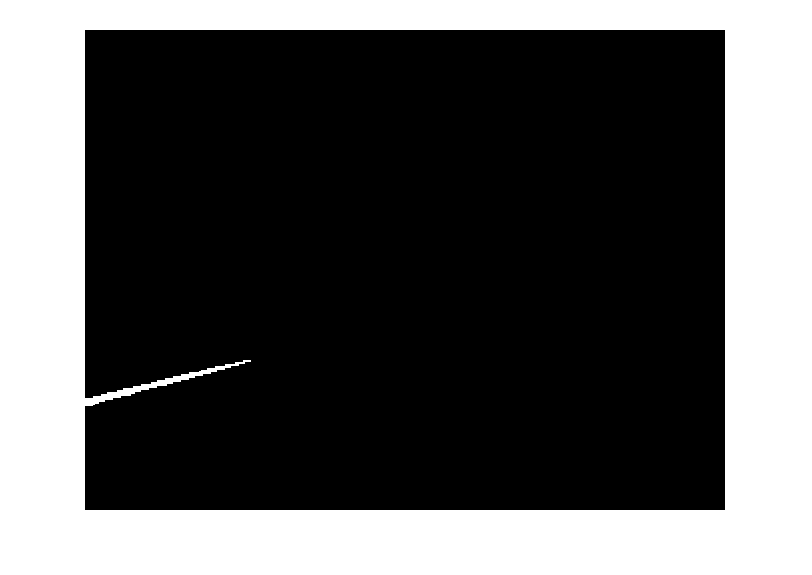

stats = regionprops( BW_blue, {'Area','Eccentricity','PixelIdxList'} );

A     = [stats.Area]';
E     = [stats.Eccentricity]';

ind   = find(E > 0.98 & A > 100);

IND   = ind(1);

new_BW_blue = false(size(BW_blue) );
new_BW_blue(stats(IND).PixelIdxList) = 1;

figure; imshow(new_BW_blue);

Process the YELLOW BW image:

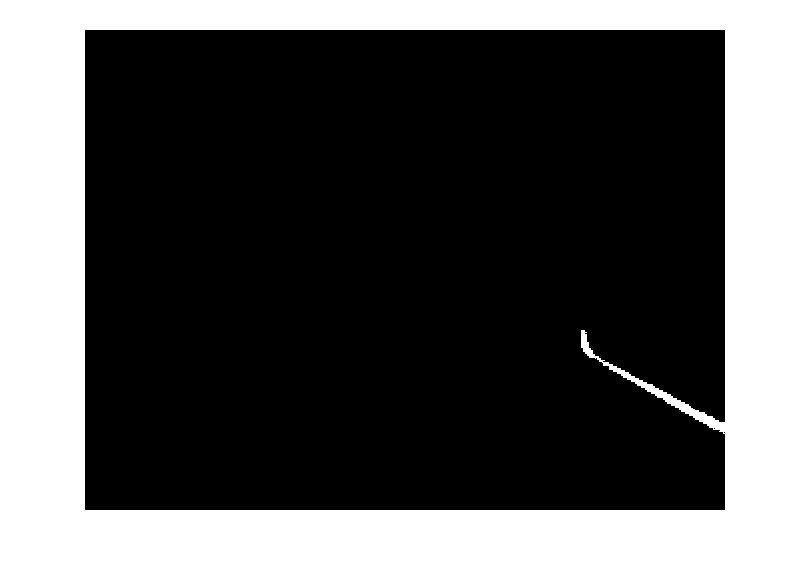

stats = regionprops( BW_yellow, {'Area','Eccentricity','PixelIdxList'} );

A     = [stats.Area]';
E     = [stats.Eccentricity]';

ind   = find(E > 0.98 & A > 100);

IND   = ind(1);

new_BW_yellow = false(size(BW_yellow) );
new_BW_yellow(stats(IND).PixelIdxList) = 1;

figure; imshow(new_BW_yellow);

## Step 6:  find the on track Obstacle boxes

Let's look for the BLUE and YELLOW lane markings:

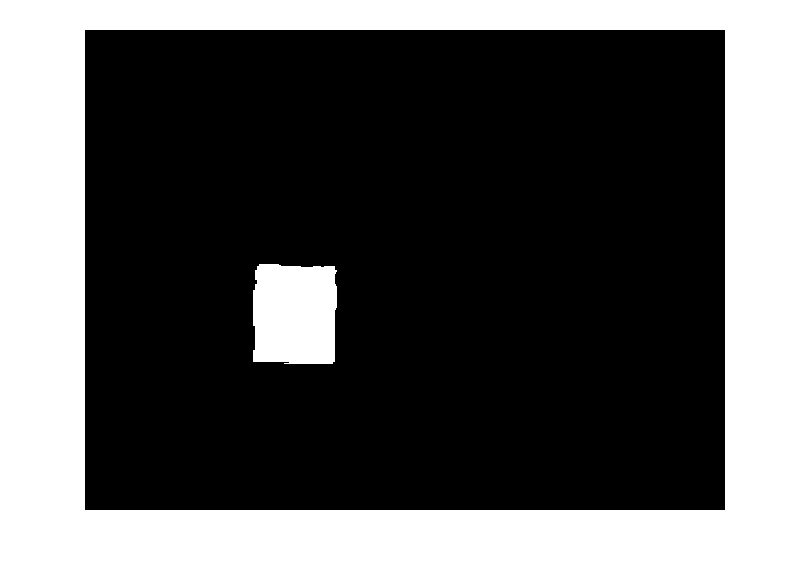

BW_purple   = label == 2;
stats = regionprops( BW_purple, {'Area','Eccentricity','PixelIdxList'} );
A     = [stats.Area]';

[~,ind] = sort(A,'descend');

stats = stats(ind);

% take the BIGGEST purple blob you can see
IND = 1;

new_BW_purple = false(size(BW_purple) );
new_BW_purple(stats(IND).PixelIdxList) = 1;

figure; imshow(new_BW_purple);